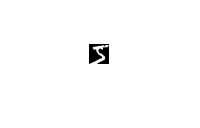

[ims, labels] = readMNIST('train-images-idx3-ubyte', 'train-labels-idx1-ubyte', 20, 0);
imshow(ims(:,:,1))

ans = 5

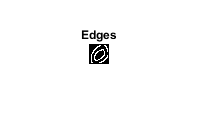

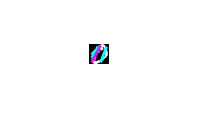

labels(1)

Agafar el 80% com a mostra i 20% per testejar el model

% [rows, cols, nims] = size(ims)
% sample = ims(:,:, 1:floor(nims*0.8));
% test = ims(:,:, floor(nims*0.8)+1:end);

data = regionprops(ims(:,:,1), 'all');
data2 = regionprops(ims(:,:,2), 'all');

size(ims, 3)

ans = 20

[ims, labels] = readMNIST('train-images-idx3-ubyte', 'train-labels-idx1-ubyte', 2000, 0);
areas = [];
centroids = [];
boundingBoxes = [];
%Features millor pensades, no les 3 primeres
eccentricities = [];
majorAxis = [];
minorAxis = [];
orientation = [];
perimeter = [];
hough = [];

for im=1:size(ims, 3)
    %regionprops
    data = regionprops(ims(:,:,im), 'all');
    areas = [areas;data.Area];
    centroids = [centroids;data.Centroid];
    boundingBoxes = [boundingBoxes;data.BoundingBox];
    eccentricities = [eccentricities; data.Eccentricity];
    majorAxis = [majorAxis; data.MajorAxisLength];
    minorAxis = [minorAxis; data.MinorAxisLength];
    orientation = [orientation; data.Orientation];
    perimeter = [perimeter; data.Perimeter];
    %Transformada de Hough
    longLines = houghTransform(ims(:,:,im));
    houghValues = [longLines.point1, longLines.point2, longLines.theta, longLines.rho];
    hough = [hough; houghValues];   
end

%no funciona
hough.Properties.VariableNames{'Var9_1'} = 'point1x';

Unable to perform assignment because dot indexing is not supported for variables of this type.

hough.Properties.VariableNames{'Var9_2'} = 'point1y';
hough.Properties.VariableNames{'Var9_3'} = 'point2x';
hough.Properties.VariableNames{'Var9_4'} = 'point2y';
hough.Properties.VariableNames{'Var9_5'} = 'theta';
hough.Properties.VariableNames{'Var9_6'} = 'rho';

t = table(areas, centroids, boundingBoxes, eccentricities, majorAxis, minorAxis, orientation, perimeter, hough(1:size(areas, 1),:), labels(1:size(areas, 1)));

ans = struct with fields:
    point1: [5 4]
    point2: [14 18]
     theta: -36
       rho: 1
